依赖[统一实验分析作图v17.1.1](https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases)

Similar activity in MOp Learned_task_A and Transfer_task_B

预加载此脚本一次即可

TransferLearning.FullCalciumPreload;

统一实验分析作图v17.1.1已发布，<a href="https://github.com/ShanghaitechGuanjisongLab/Unified-Experimental-Analysis-and-Figuring/releases">立即更新</a>


不能按照达峰时间排序

MOpAuc=MOpNtats;
MOpAuc.NTATS=MOpAuc.NTATS(:,:,["Naive_cue1","Naive_cue1_water","Learned4_cue1_water","Transfer_cue2_water"]);
MOpAuc=UniExp.HeatmapSort(MOpAuc,UniExp.Flags.Mean);

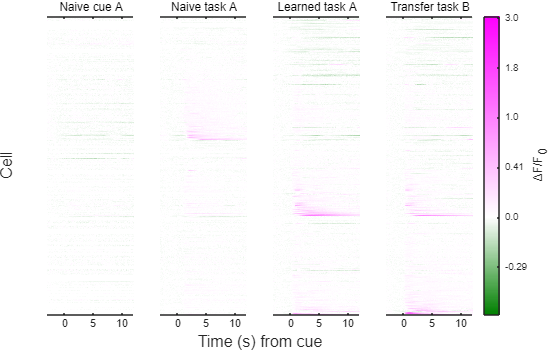

figure;
Layout=tiledlayout(1,4,TileSpacing='tight',Padding='tight');
UniExp.LanearHeatmap(MOpAuc.NTATS,UniExp.Flags.HideYAxis,Layout=Layout,ImagescStyle={'XData',[-3,12]},SubTitles=["Naive cue A","Naive task A","Learned task A","Transfer task B"]);
ylabel(Layout,'Cell');
xlabel(Layout,'Time (s) from cue');
CB=colorbar;
CB.Label.String='ΔF/F_0';
CB.TickLabels=MATLAB.SignificantFixedpoint(2.^str2double(CB.TickLabels)-1,2);
MATLAB.Graphics.FigureAspectRatio(8,5,MATLAB.Flags.Narrow);
print('Fig1E.svg','-dsvg');